addpath("helpers","helpers\nextname")

data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-end_side_sw_0\measurement_003";

dr = dca1000FileReader("RecordLocation", data_src);
iwr = IWR1843(data_src);
srcParts = split(data_src, "\");
dataName = join(srcParts(end-1:end), "-");
clear srcParts

isEndRecording = contains(dataName, "hall-end");
mode=2;

rangeLimits = [0.5, 9]; % m
angFftLength = 64;

numFrames = min([dr.NumDataCubes, 2e3]);
angGrid = iwr.mvdrEstimator.ScanAngles;

rngWin = hamming(iwr.config.SamplesPerChirp);
dopWin = hamming(iwr.config.NumChirps/sum(iwr.config.ActiveTransmitters))';

rngGrid = (0:iwr.config.SamplesPerChirp - 1) * iwr.config.RangeResolution;
[rngIdxs, rngGrid] = getLimitedIndexRangesFromDataRanges(rngGrid, rangeLimits);

rangeBins = numel(rngGrid);
angleBins = numel(angGrid);
dopBins = numel(dopWin);
dopGrid = (-dopBins/2:dopBins/2-1)*iwr.config.RangeRateResolution;

angFftGrid=asind((0:angFftLength-1)*2/angFftLength-1);

radarAngle = -17;

if isEndRecording
    corDim = [4 9];
    wMask = corridorMap(angGrid, rngGrid, corDim, [0.5 1 90 + radarAngle]);
    wallCutoff = rngGrid(sum(wMask,1));
    cartPlotLimitsX = [-5 3];
else
    wallDistance = 2.7; % m
    wallCutoff = wallDistance./cosd(angGrid);
    cartPlotLimitsX = [-3 5];
end
wMask=ones(rangeBins,dopBins,"logical");

% CFAR
% [rangeDim dopplerDim]
guardCells = [5 4];
trainCells = [3 6];
fap = 9;
method = "GOCA";

cfar = CFAR(guardCells,trainCells,fap,method,wMask);

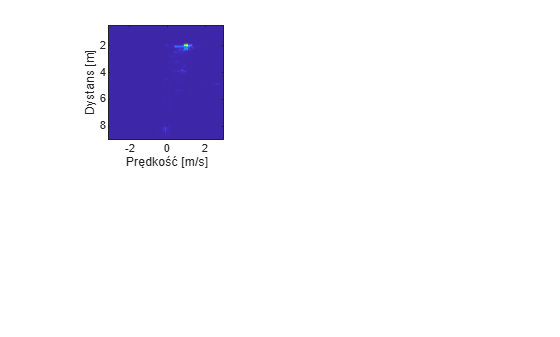

bgFilterFrameCount = 100; % @25 fps

angleLimits=angGrid([1 end]);
[angFftIdx,angFftGrid] = getLimitedIndexRangesFromDataRanges(angFftGrid,angleLimits);

tracker = radarTracker( ...
    FilterInitializationFcn=@initcvekf, ...
    ConfirmationThreshold=[6 10], ...
    AssignmentThreshold=[10 30],...
    DeletionThreshold=8, ...
    MaxNumTracks=5 ...
    );

warning('off','shared_tracking:internal:GNNTracker:MaxNumTracksReached');

mp = struct(Frame="Spherical", ...
    OriginPosition = zeros(1,3), ...
    OriginVelocity = zeros(1,3), ...
    Orientation=rotz(-90), ...
    HasAzimuth = true,...
    HasElevation = false,...
    HasRange = true,...
    HasVelocity = true,...
    IsParentToChild = true);

colors = lines;

filterInited = false;
tracker({objectDetection(0,[0 1 0],"MeasurementParameters",mp)}, 0);
trackLog = cell(numFrames,1);
targetsLog = cell(numFrames,1);

timesDesc = ["Tworzenie mapy", "CFAR", "Filtracja detekcji", "Śledzenie"];
times = zeros(numel(timesDesc),numFrames);
detStat = zeros(3,numFrames);

% BG = bgFilter(zeros(rangeBins,dopBins), bgFilterFrameCount);
for frN=200:numFrames
    srcCube = dr.read(1, frN);
    tic;
    srcCube = iwr.arrangeVirtualDataAngleULA(srcCube);
    cube = fft(srcCube.*rngWin, [], 1); % fast time FFT
    cube = cube(rngIdxs, :, :); % cut cube to rangeLimits
    cube = cube - mean(cube,3); % static clutter removal
    cube = fftshift(fft(cube.*reshape(dopWin, 1, 1, []),[],3),3); % slow time (Doppler) FFT
    
    RD = squeeze(sum(abs(cube),2));
    % if frN==1
    %     BG = bgFilter(RD, bgFilterFrameCount);
    % end

    % RDM = BG.addSampleNoBg(RD, 0.99);
    % RDM(RDM<0) = 0;
    % RDM = log10(RDM);
    RDM = RD;
    times(1,frN) = toc;
    tic;
    [dets,mask] = cfar.runCFAR2D(RDM);
    times(2,frN) = toc;
    detStat(1,frN) = size(dets,2);
    targets = zeros(6,size(dets,2));
    subplot(2,2,1)
    imagesc(dopGrid, rngGrid, RDM);
    xlabel("Prędkość [m/s]")
    ylabel("Dystans [m]")
    pbaspect([1 1 1]);
    subplot(2,2,2)
    imagesc(dopGrid,rngGrid,mask)
    tic
    for detNr=1:size(dets,2)
        det = dets(:,detNr);
        angSpectrum = iwr.mvdrEstimator(squeeze(cube(det(1),:,det(2)-4:det(2)+4))');
        [~,idx] = max(angSpectrum);
        rng=rngGrid(det(1));
        if mode==2 && rng >= wallCutoff(idx)
            continue % leave the column zeroed
        end
        ang=iwr.mvdrEstimator.ScanAngles(idx);
        % angFftSpectrum = fftshift(fft(cube(det(1),:,det(2)),angFftLength));
        % [~,idx] = max(angFftSpectrum(angFftIdx));
        % ang = angFftGrid(idx);
        [x, y] = pol2cart(deg2rad(ang+90), rng);
        targets(:,detNr)= [x y ang rng dopGrid(det(2)) RDM(det(1),det(2))];
    end

    % figure(2);
    % plt = data;
    % plt(~(mask.*wMask)) = min(data, [], "all");
    % show3D(angGrid, rngGrid, plt);

    if mode==2
        targets = targets(:, targets(end,:)>0);
    end
    
    detStat(2,frN) = size(dets,2);

    targets = doDbscan(targets, 0.5, 3);
    times(3,frN) = toc;
    detStat(3,frN) = size(targets,2);

    figure(3);
    subplot(2,2,[3 4])
    if isEndRecording
        maxY = rngGrid(end);
    else
        maxY=wallDistance;
    end
    % plotWithRadarFov(targets(1,:),targets(2,:),angleLimits,cartPlotLimitsX,[0 maxY]);
    % hold on
    % plot(targets(1,:),targets(2,:),"o","MarkerEdgeColor","b")
    % hold off
    % title("Ramka "+num2str(frN))
    tic
    numDets = size(targets,2);
    trackDets = cell(1,numDets);
    time = frN*iwr.config.FramePeriodicity*1e-3;
    for k=1:numDets
        trackDets{k} = objectDetection(time, targets(3:5,k),MeasurementParameters=mp);
    end
    [tracks,tentativeTracks,allTracks]= tracker(trackDets, time);
    times(4,frN) = toc;
    trackLog{frN} = tracks';
    targetsLog{frN} = targets([1 2 6],:);
    % plotTrackerState(tracks,colors);

    drawnow limitrate
end

prctile(sum(times,1),99)
stat=nextname(data_src,"RD_stats_<01>.mat")
save(data_src+"\"+stat, "times","detStat", '-mat');

ts = numel(timesDesc);
figure(10)
clf
for n=1:ts
    subplot(ts,1,n)
    histogram(times(n,:))
    ylabel(timesDesc(n))
end
sgtitle("Histogramy czasów realizacji części procesu RD")

figure(11)
clf
scatter(detStat(1,:),detStat(3,:))
xlabel("Liczba detekcji CFAR")
ylabel("Liczba przetwarzanych detekcji")

figure(12)
clf
boxchart([times;sum(times,1)]')
xticklabels([timesDesc, "Suma"])
ylabel("Czas [s]")
title("Rozkład czasu realizacji części procesu RD")

trackLogArr = [trackLog{:}];
trackLogArr = [trackLogArr(:).State; trackLogArr(:).UpdateTime; double([trackLogArr(:).TrackID])];

gndTruth = [3 3 6 6 3; 0 23 23 6 6]*0.305;

figure(20)
clf
if isEndRecording
    subplot(1,2,1)
    plot(gndTruth(1,:),gndTruth(2,:),":","Color","#aaaaaa","LineWidth",2);
    rotMat = rotz(-17);
    rotMat = rotMat(1:2,1:2);
else
    rotMat = eye(2,2);
end
ids = unique(trackLogArr(end,:));
for id=ids
    subplot(1,2,1)
    part = trackLogArr(:,trackLogArr(end,:)==id);
    XY=rotMat*part([1 3],:); % rotate according to radar position
    hold on
    plot(XY(1,:),XY(2,:)); % trail
    hold off
    subplot(1,2,2)
    hold on
    plot(part(end-1,:),hypot(part(2,:),part(4,:))); % speed
    hold off
end
subplot(1,2,1)
xlabel("Dystans [m]")
ylabel("Dystans [m]")
hold on
plot(0,0,"v",'Color','r','LineWidth',1)
ylim([0 maxY])
xlim(cartPlotLimitsX)
axis equal fill;
hold off
subplot(1,2,2)
% legend(string(ids),"NumColumns",2)
xlabel("Czas [s]")
ylabel("Prędkość [m/s]")
sgtitle("Śledzone ścieżki w procesie RD")

figure(21)
clf
tLog = [targetsLog{:}];
tLog(1:2, :) = rotMat * tLog(1:2, :);
hold on
scatter(tLog(1,:), tLog(2,:), 40, tLog(3,:), '*')
if isEndRecording
    plot(gndTruth(1,:),gndTruth(2,:),":","Color","#aaaaaa","LineWidth",2);
end
hold off
title("Punkty analizowane w procesie RD")
xlabel("Dystans [m]")
ylabel("Dystans [m]")

function detections = doDbscan(targets,epsilon,minpts)
    if isempty(targets)
        detections=targets;
        return
    end
    clust = dbscan(targets(1:2,:)',epsilon,minpts);
    ids = unique(clust);
    ids=ids(ids>0);
    detections = zeros(size(targets,1),numel(ids));
    for i=1:numel(ids)
        part = targets(:,clust==ids(i));
        % detections(:,i)=mean(part,2);
        detections(:,i)=mean(part,2,"Weights",part(6,:));
    end
end

function plotWithRadarFov(X,Y,angLim,xLim,yLim)
plot(X,Y, '*',"MarkerEdgeColor","r");
xlim(xLim);
ylim(yLim);
axis equal;
grid on
hold on
yVal=xLim.*tand(90-sort(angLim));
plot([xLim(1) 0 xLim(2)],[yVal(1) 0 yVal(2)],"Color","cyan")
hold off
end

function plotTrackerState(tracks,colors)
hold on
for obj=1:numel(tracks)
    coord = num2cell(tracks(obj).State([1 3 2 4]));
    color = colors(mod(tracks(obj).TrackID,size(colors,1))+1,:);
    plot(coord{1},coord{2},"o","MarkerFaceColor",color,"MarkerSize",10)
    quiver(coord{:},'Color',color);
end
hold off
end